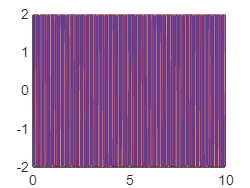

% time_x = {ent_sen_2_1_Time, ent_sen_2_2_Time, ent_sen_2_3_Time, ent_sen_2_4_Time, ent_sen_2_5_Time, ent_sen_2_6_Time, ent_sen_2_7_Time, ent_sen_2_8_Time, ent_sen_2_9_Time, ent_sen_2_10_Time};
% time_y = {sai_sen_2_1_Time(:,1), sai_sen_2_2_Time(:,1), sai_sen_2_3_Time(:,1), sai_sen_2_4_Time(:,1), sai_sen_2_5_Time(:,1), sai_sen_2_6_Time(:,1), sai_sen_2_7_Time(:,1), sai_sen_2_8_Time(:,1), sai_sen_2_9_Time(:,1), sai_sen_2_10_Time(:,1)};
% 
% x = {ent_sen_2_1_Value, ent_sen_2_2_Value, ent_sen_2_3_Value, ent_sen_2_4_Value, ent_sen_2_5_Value, ent_sen_2_6_Value, ent_sen_2_7_Value, ent_sen_2_8_Value, ent_sen_2_9_Value, ent_sen_2_10_Value};
% y = {sai_sen_2_1_Value(:,1), sai_sen_2_2_Value(:,1), sai_sen_2_3_Value(:,1), sai_sen_2_4_Value(:,1), sai_sen_2_5_Value(:,1), sai_sen_2_6_Value(:,1), sai_sen_2_7_Value(:,1), sai_sen_2_8_Value(:,1), sai_sen_2_9_Value(:,1), sai_sen_2_10_Value(:,1)};

time_x = {sqrf1000a200Ent_Time(:,1), sqrf100a200Ent_Time(:,1), sqrf200a200Ent_Time(:,1), sqrf500a200Ent_Time(:,1)};
time_y = {sqrf1000a200Sai_Time(:,1), sqrf100a200Sai_Time(:,1), sqrf200a200Sai_Time(:,1), sqrf500a200Sai_Time(:,1)};

x = {sqrf1000a200Ent_Value, sqrf100a200Ent_Value, sqrf200a200Ent_Value, sqrf500a200Ent_Value};
y = {sqrf1000a200Sai_Value, sqrf100a200Sai_Value, sqrf200a200Sai_Value, sqrf500a200Sai_Value};


graf_init = 1;
graf_end = 4;

for i = graf_init:graf_end
    time_x{i}= time_x{i}-time_x{i}(1);
    plot(time_x{i},x{i})
    hold on
end
hold off

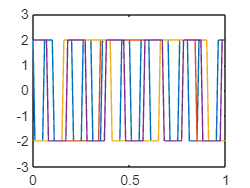

range_time_x = zeros(length(0:0.01:1), graf_end-graf_init+1);
range_x = zeros(length(0:0.01:1), graf_end-graf_init+1);

for i = graf_init:graf_end
    for j = 0:100
        range_time_x(j+1, i)= time_x{i}(length(time_x{i})-100+j)-time_x{i}(length(time_x{i})-100);
        range_x(j+1, i)= x{i}(length(time_x{i})-100+j);
    end
end

range_time_y = zeros(length(0:0.01:1), graf_end-graf_init+1);
range_y = zeros(length(0:0.01:1), graf_end-graf_init+1);

for i = graf_init:graf_end
    for j = 0:100
        range_time_y(j+1, i)= time_y{i}(length(time_y{i})-100+j)-time_y{i}(length(time_y{i})-100);
        range_y(j+1, i)= y{i}(length(time_y{i})-100+j);
    end
end

plot(range_time_x(:,:),range_x(:,:))
ylim([-3 3])

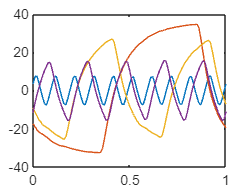


plot(range_time_y(:,:),range_y(:,:))

x_mx_fft = fft(range_x);
y_mx_fft = fft(range_y);

[x_max, x_ind] = max(abs(x_mx_fft));
[y_max, y_ind] = max(abs(y_mx_fft));

x_angle_max = angle(x_mx_fft(x_ind));
y_angle_max = angle(y_mx_fft(y_ind));

phaseResponse2 = y_angle_max - x_angle_max;

magnitudeResponse2 = y_max./x_max;

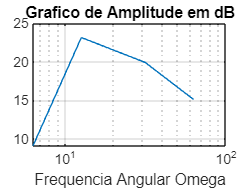

%pegando as frequências medidas
%frequencySample

%frequencies = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10];
frequencies = [1, 2, 5, 10];


omega2 = zeros(1, graf_end-graf_init+1);
ampl2 = zeros(1, graf_end-graf_init+1);


for i = graf_init:graf_end
    omega2(i) = 2*pi*frequencies(1,i);
    ampl2(i) = 20*log10(magnitudeResponse2(1,i));
end

semilogx(omega2,ampl2,'-')
title('Grafico de Amplitude em dB');
xlabel ('Frequencia Angular Omega') ;

grid on

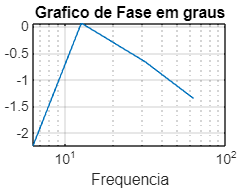


fase2 = zeros(1, graf_end-graf_init+1);

for i = graf_init:graf_end
    fase2(i) = phaseResponse2(i);
end

semilogx(omega2, fase2)
title ('Grafico de Fase em graus');
xlabel ('Frequencia');

grid on

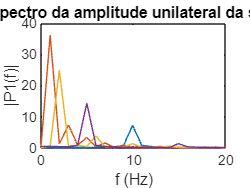

N = length(y_mx_fft(:,1));
frequencySample = 1/0.01;
frequenciesSample = frequencySample*(0:(N/2))/N;


P2 = abs(y_mx_fft/N);
P1 = P2(1:floor(N/2)+1,:);
P1(2:end-1) = 2*P1(2:end-1);

for i = graf_init:graf_end
    plot(frequenciesSample,P1(:,i))
    hold on
end
hold off

title("Espectro da amplitude unilateral da saída")
xlabel("f (Hz)")
ylabel("|P1(f)|")
xlim([0 20])